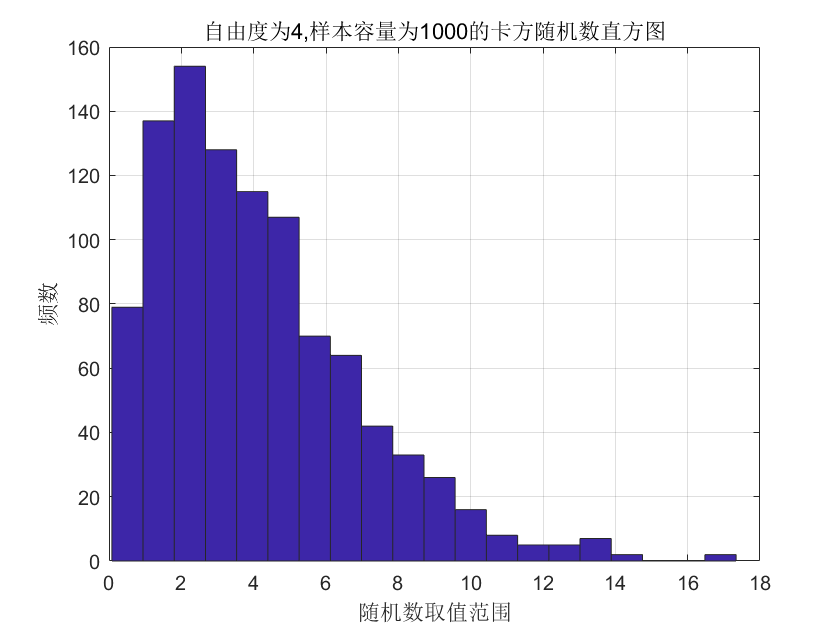

% 实验9 卡方分布随机数
n = 4;      % 自由度
cpc = 1000; % 样本容量
normrnds = myrand(n * cpc); 
nums = zeros(1, cpc);
for i = 1:cpc
    %nums(i) = rndchi2(n);      % 此行使用内置函数生成正态分布随机数
    nums(i) = rangedRndchi2(normrnds, 4 * (i - 1) + 1, 4 * i);
end
figure(1);
hist(nums, round(cpc / 50));
grid on; axis on;
xlabel("随机数取值范围");
ylabel("频数");
str = sprintf("自由度为%d,样本容量为%d的卡方随机数直方图", n, cpc);
title(str);

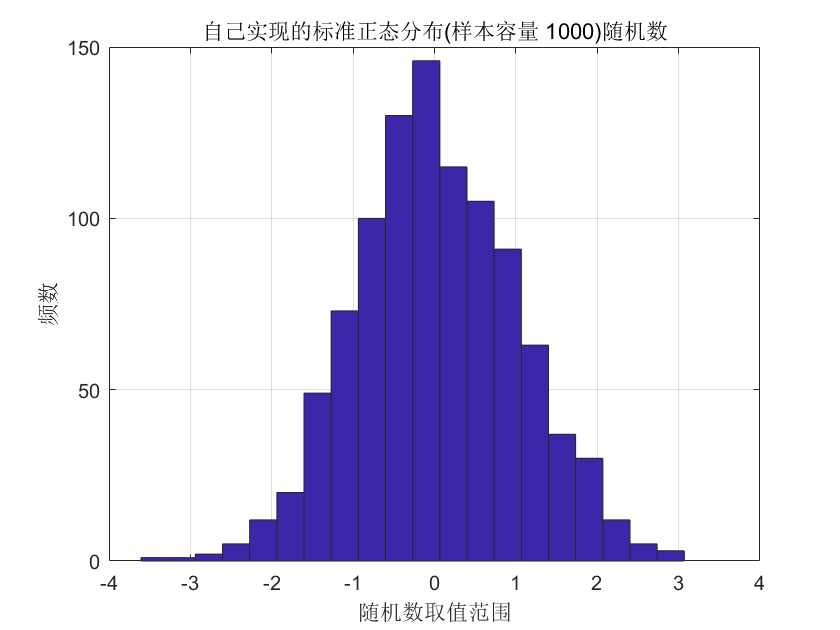

figure(2);
hist(myrand(cpc), 20);
grid on; axis on;
xlabel("随机数取值范围");
ylabel("频数");
str = sprintf("自己实现的标准正态分布(样本容量 %d)随机数", cpc);
title(str);



% matlab 内置函数有chi2rnd用于生成卡方随机数，在这里就不使用了

function out = rndchi2(n)
% 自由度为n的卡方随机数, 默认返回行向量
% 使用内置的normrnd 实现的卡方随机数
x = normrnd(0, 1, 1, n);
out = norm(x, 2) ^ 2;              % 矩阵点乘求和
end

function out = rangedRndchi2(rnds, s, e)
% 对正态分布随机数列表进行卡方数转换
% rnd 正态向量
% s 起始位置
% e 中止位置
out = norm(rnds(1, s:e), 2) ^ 2;
end

function out = myrand(n)
% 自己写的正态随机数
% n size
rnd = zeros(1, n);
sd = seed();
x = floor(sd / 3);
for i = 1:n
    x = mod(101 * x + 7, seed);
    rnd(i) = norminv(x / seed);     % 正态分布反函数
end
out = rnd;
end

function out = seed()
% 根据当前时间生成随机数种子
date_vec = clock();
out = date_vec(1) ^ 2;
for i = 2:2:4
    out = out + (date_vec(i) + date_vec(i + 1)) ^ 2;
end
out = out + ceil(date_vec(6) ^ 3);
end